clear all
close all
clc

s=tf('s');

[file_controllers, file_path] = uigetfile("controller_*.mat", "Controller");
load([file_path file_controllers])

[file_name, file_path] = uigetfile("*.mat", "Modello1");
load([file_path file_name])

[file_name, file_path] = uigetfile("*.mat", "Modello2");
load([file_path file_name])

F1_in=minreal(feedback(C1_in*modello_continuo_tf_j1,1))

F1_in =
 
  From input "u1" to output:
               1657 s^3 + 3.442e05 s^2 + 2.526e08 s + 2.776e09
  -------------------------------------------------------------------------
  0.01026 s^5 + 4.056 s^4 + 6507 s^3 + 1.185e06 s^2 + 2.914e08 s + 2.776e09
 
Continuous-time transfer function.



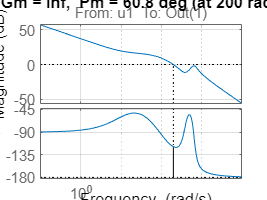

margin(C1_in*modello_continuo_tf_j1)
grid on


F2_in=minreal(feedback(C2_in*modello_continuo_tf_j2,1))

F2_in =
 
  From input "u1" to output:
               1391 s^3 + 1.579e05 s^2 + 4.962e08 s + 3.385e09
  --------------------------------------------------------------------------
  0.003413 s^5 + 2.775 s^4 + 5290 s^3 + 1.454e06 s^2 + 5.858e08 s + 3.385e09
 
Continuous-time transfer function.



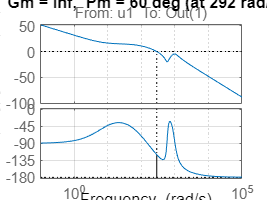

margin(C2_in*modello_continuo_tf_j2)
grid on

[Y1,T1]=step(F1_in);
t1_1=T1(min(find(Y1>=Y1(end)*0.0952)));
t1_2=T1(min(find(Y1>=Y1(end)*0.6321)));
syms t tau;
eqn1 = t1_1 == t+0.1*tau;
eqn2 = t1_2 == t + tau;
sol=solve([eqn1;eqn2]);
delay1_in=double(sol.t)

delay1_in = 8.9982e-04

tau1_in=double(sol.tau)

tau1_in = 0.0038

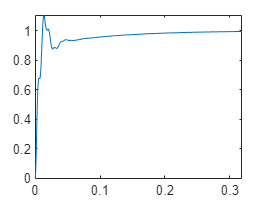

plot(T1,Y1)

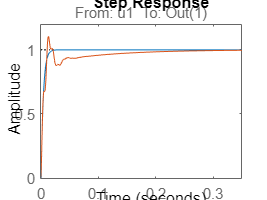

F1_in_approx = tf(1, [tau1_in 1]);
F1_in_approx.OutputDelay=delay1_in;
step(F1_in_approx,F1_in)




[Y2, T2]=step(F2_in);
t2_1=T2(min(find(Y2>=Y2(end)*0.0952)))

t2_1 = 0.0010

t2_2=T2(min(find(Y2>=Y2(end)*0.6321)))

t2_2 = 0.0055

syms t tau
eqn1 = t2_1 == t+0.1*tau;
eqn2 = t2_2 == t + tau;
sol=solve([eqn1;eqn2])

sol = struct with fields:
      t: 5565499797632057/10376293541461622784
    tau: 51679640978011945/10376293541461622784


delay2_in=double(sol.t)

delay2_in = 5.3637e-04

tau2_in=double(sol.tau)

tau2_in = 0.0050

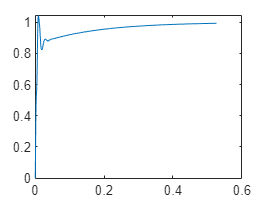

plot(T2,Y2)

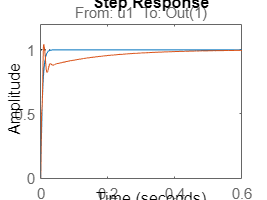

F2_in_approx = tf(1, [tau2_in 1]);
F2_in_approx.OutputDelay=delay2_in;
step(F2_in_approx,F2_in)

M1=tf(1,[tau1_in 1]);
M1.OutputDelay=delay1_in;

M2=tf(1,[tau2_in 1]);
M2.OutputDelay=delay2_in;


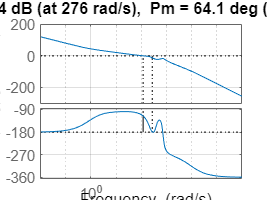


L1_out = C1_out*F1_in/s;
F1_out = feedback(L1_out,1);
margin(L1_out)
grid on

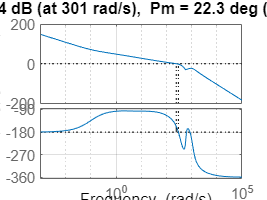


L2_out = minreal(C2_out*F2_in/s);
F2_out = feedback(L2_out,1);
margin(L2_out)
grid on

[Y1,T1]=step(F1_out);
t1_1=T1(min(find(Y1>=Y1(end)*0.0952)));
t1_2=T1(min(find(Y1>=Y1(end)*0.6321)));
syms t tau;
eqn1 = t1_1 == t+0.1*tau;
eqn2 = t1_2 == t + tau;
sol=solve([eqn1;eqn2]);
delay1_out=double(sol.t)

delay1_out = 0.0030

tau1_out=double(sol.tau)

tau1_out = 0.0086

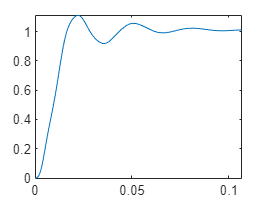

plot(T1,Y1)

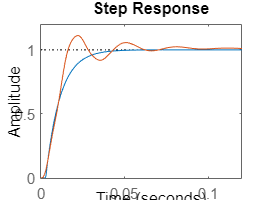

F1_in_approx = tf(1, [tau1_out 1]);
F1_in_approx.OutputDelay=delay1_out;
step(F1_in_approx,F1_out)




[Y2, T2]=step(F2_out);
t2_1=T2(min(find(Y2>=Y2(end)*0.0952)))

t2_1 = 0

t2_2=T2(min(find(Y2>=Y2(end)*0.6321)))

t2_2 = 0

syms t tau
eqn1 = t2_1 == t+0.1*tau;
eqn2 = t2_2 == t + tau;
sol=solve([eqn1;eqn2])

sol = struct with fields:
      t: 0
    tau: 0


delay2_out=double(sol.t)

delay2_out = 0

tau2_out=double(sol.tau)

tau2_out = 0

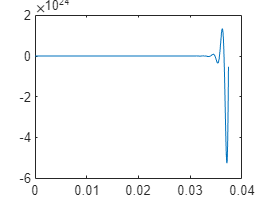

plot(T2,Y2)

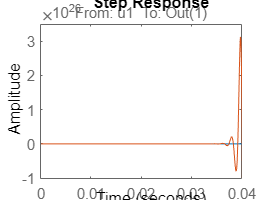

F2_in_approx = tf(1, [tau2_out 1]);
F2_in_approx.OutputDelay=delay2_out;
step(F2_in_approx,F2_out)

save(file_controllers+"_ff.mat","C1_out_ff","C1_in","tau1_in","C2_out_ff","C2_in","tau2_in");